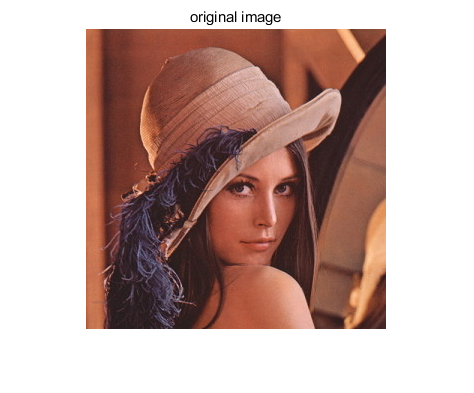

clear;
clc;
close all;
% read a image
img = imread('lena.jpg');
imshow(img);
title('original image');


% rotation degree
degree = 45;

% image size after rotation
[m, n, o] = size(img);
new_m = ceil(abs(m*cosd(degree)) + abs(n*sind(degree)));
new_n = ceil(abs(n*cosd(degree)) + abs(m*sind(degree)));

new_img_forward = zeros(new_m, new_n, o); % forward mapping
new_img_nnp = zeros(new_m, new_n, o); % reverse mapping, nearest neighbor interpolation
new_img_lp = zeros(new_m, new_n, o); % reverse mapping, bilinear interpolation

## forward mapping

forward mapping matrices

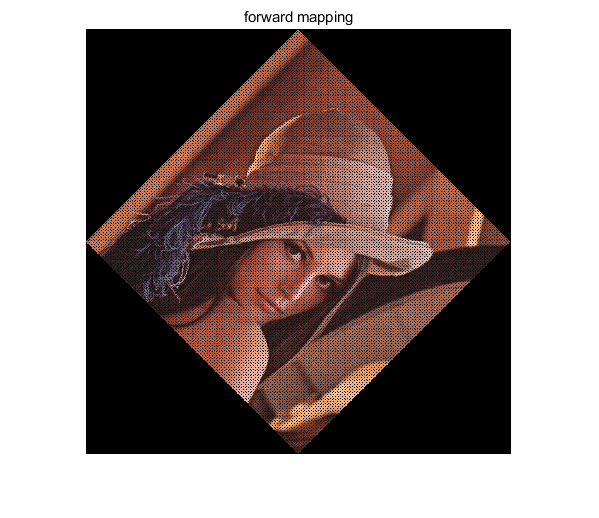

m1 = [1 0 0; 0 -1 0; -0.5*n 0.5*m 1];
m2 = [cosd(degree) -sind(degree) 0; sind(degree) cosd(degree) 0; 0 0 1];
m3 = [1 0 0; 0 -1 0; 0.5*new_n 0.5*new_m 1];

for i = 1:n
   for j = 1:m
      new_coordinate = [i j 1]*m1*m2*m3;
      col = round(new_coordinate(1));
      row = round(new_coordinate(2));
      % no-rotation image's coordinates to rotated image's coordinates
      new_img_forward(row, col, 1) = img(j, i, 1);
      new_img_forward(row, col, 2) = img(j, i, 2);
      new_img_forward(row, col, 3) = img(j, i, 3);
   end
end
figure, imshow(new_img_forward/255), title('forward mapping');

## reverse mapping

reverse mapping matrices

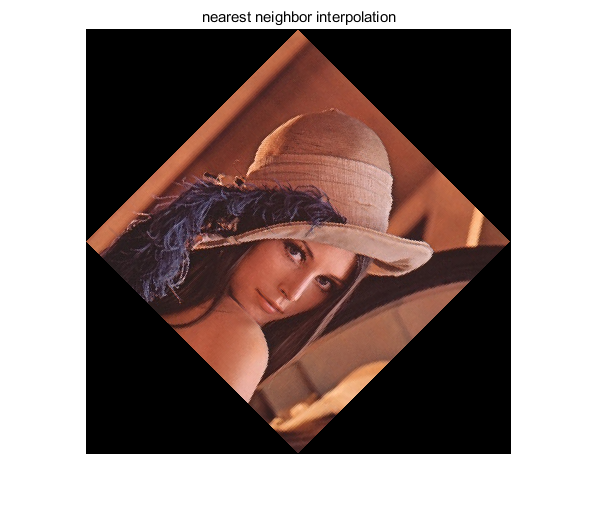

rm1 = [1 0 0; 0 -1 0; -0.5*new_n 0.5*new_m 1];
rm2 = [cosd(degree) sind(degree) 0; -sind(degree) cosd(degree) 0; 0 0 1];
rm3 = [1 0 0; 0 -1 0; 0.5*n 0.5*m 1];

for i = 1:new_n
   for j = 1:new_m
       % rotated image's coordinates to no-rotation image's coordinates
      old_coordinate = [i j 1]*rm1*rm2*rm3;
      col = round(old_coordinate(1));
      row = round(old_coordinate(2));
      % prevent border overflow 
      if row < 1 || col < 1 || row > m || col > n
          new_img_nnp(j, i) = 0;
          new_img_lp(j, i) = 0;
      else
          % nearest neighbor interpolation
          new_img_nnp(j, i, 1) = img(row, col, 1);
          new_img_nnp(j, i, 2) = img(row, col, 2);
          new_img_nnp(j, i, 3) = img(row, col, 3);
          
          % bilinear interpolation
          left = floor(col);
          right = ceil(col);
          top = floor(row);
          bottom = ceil(row);
          
          a = col - left;
          b = row - top;
          new_img_lp(j, i, 1) = (1-a)*(1-b)*img(top, left, 1) + a*(1-b)*img(top, right, 1) + ...
              (1-a)*b*img(bottom, left, 1) + a*b*img(bottom, right, 1);
          new_img_lp(j, i, 2) = (1-a)*(1-b)*img(top, left, 2) + a*(1-b)*img(top, right, 2) + ...
              (1-a)*b*img(bottom, left, 2) + a*b*img(bottom, right, 2);
          new_img_lp(j, i, 3) = (1-a)*(1-b)*img(top, left, 3) + a*(1-b)*img(top, right, 3) + ...
              (1-a)*b*img(bottom, left, 2) + a*b*img(bottom, right, 3);
      end
   end
end
figure, imshow(new_img_nnp/255), title('nearest neighbor interpolation');

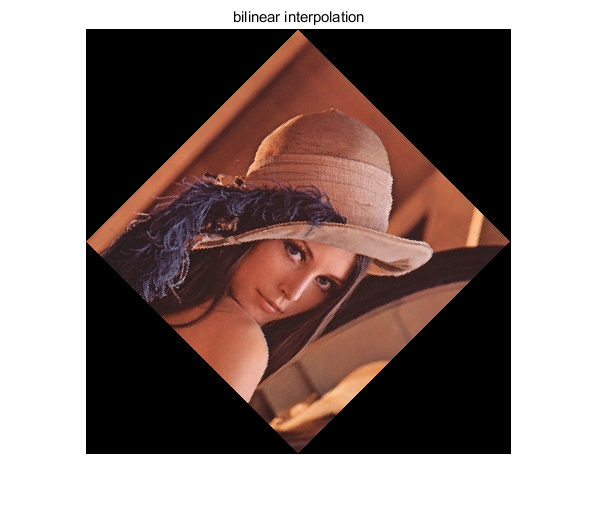

figure, imshow(new_img_lp/255), title('bilinear interpolation');